# Varying correlation; gap length

## load and preprocess data

fds = fileDatastore('A1-*.mat', 'ReadFcn', @importdata);
Filenames = fds.Files;
ncorr = length(Filenames);

C = cell(1,ncorr);
for i = 1:ncorr
    load(Filenames{i});
    C{1,i} = c;
end

c = cat(1,C{1,:});

nparams = size(c,1); % number of sets of firing rate parameters
ntrials = size(c,2)-5; % number of trials
Corr = zeros(nparams, ntrials);
for i = 1:nparams
    for j = 1:ntrials
        Corr(i,j)=c{i,j}.corr;
    end
end

params = c(:,ntrials+1:ntrials+5);
params = cell2mat(params);
lambda1 = params(:,1);
lambda2 = params(:,2);
k1 = params(:,3);
k2 = params(:,4);
fr_exact = params(:,5);
fr = round(fr_exact,-1); % round firing rate to nearest 10 Hz
fr1 = lambda1./k1; % bursting firing rate
fr2 = lambda2./k2;
fr1 = round(fr1,-1);
fr2_round = round(fr2);
burstiness = k1./lambda1;

Corr = median(Corr,2);
Corr(Corr<0)=0;
corr_edges = 0:0.1:1;
corr_bin = discretize(Corr,corr_edges);
corr_vec1 = 0:0.1:1;
corr_vec2 = 0.05:0.1:0.95;

fr_vals = 10:10:100;
corr_vals = 1:length(corr_edges)-1;

## analyze data: part 1

% get exponential fit between dimensionless time constant and dimensionless
% gap length
warning('off','all')
A = zeros(10,length(corr_vals));
B = zeros(10,length(corr_vals));

for k = 1:length(corr_vals)
    for l = 1:10
        rows = find(fr2_round == l & corr_bin==k);
        if ~isempty(rows)
            all_X = [];
            all_Y = [];
            for j = 1:length(rows)
                row = rows(j);  
                tau_vec = c{row,1}.performance(:,1);
                Gap = zeros(length(tau_vec),ntrials);
                for i = 1:ntrials
                    Gap(:,i) = c{row,i}.performance(:,2);
                end
                Gap2 = reshape(Gap,1,[]);
                Tau = repmat(tau_vec,ntrials,1); 
                X = Tau.*fr_exact(row)./1000;
                Y = Gap2.*fr_exact(row)./1000;
                % can average Y values that have the same X value (average across
                % trials)
                X_vals = unique(X);
                Y_vals = zeros(length(X_vals),1);
                for i = 1:length(X_vals)
                    Y_vals(i) = median(Y(X==X_vals(i)),'omitnan');
                end
                all_X = [all_X; X_vals];
                all_Y = [all_Y; Y_vals];
            end
            % now average together all points that have the same x value
            all_X1 = unique(all_X);
            all_Y1 = zeros(length(all_X1),1);
            for i = 1:length(all_X1)
                all_Y1(i) = median(all_Y(all_X==all_X1(i)),'omitnan');
            end
            
            mdl = fitlm(log(all_X1),log(all_Y1));
            a = mdl.Coefficients.Estimate(1);
            b = mdl.Coefficients.Estimate(2);
            A(l,k) = a;
            B(l,k) = b;
        end        
    end
end

% compute NRMSE of fits
warning('off','all')
NRMSE = nan(size(c,1),ntrials);

for k = 1:length(corr_vals)
    for l = 1:10
        rows = find(fr2_round == l & corr_bin==k);
        if ~isempty(rows)
            all_X = [];
            all_Y = [];
            for j = 1:length(rows)
                row = rows(j);  
                tau_vec = c{row,1}.performance(:,1);
                Gap = zeros(length(tau_vec),ntrials);
                X_vals = tau_vec.*fr_exact(row)./1000;
                a = A(l,k);
                b = B(l,k);
                for i = 1:ntrials
                    Gap(:,i) = c{row,i}.performance(:,2);                                 
                end
                Gap2 = reshape(Gap,1,[]);
                Tau = repmat(tau_vec,ntrials,1);    
                X = Tau.*fr_exact(row)./1000;
                Y = Gap2.*fr_exact(row)./1000;
                % can average Y values that have the same X value (average across
                % trials)
                X_vals = unique(X);
                Y_vals = zeros(length(X_vals),1);
                for i = 1:length(X_vals)
                    Y_vals(i) = median(Y(X==X_vals(i)),'omitnan');
                end
                
                [~, goodness] = createFit1(log(X_vals),log(Y_vals),a,b);
                NRMSE(row) = goodness.rmse/mean(log(Y_vals),'omitnan');
            end
        end        
    end
end

## example plots shown in paper

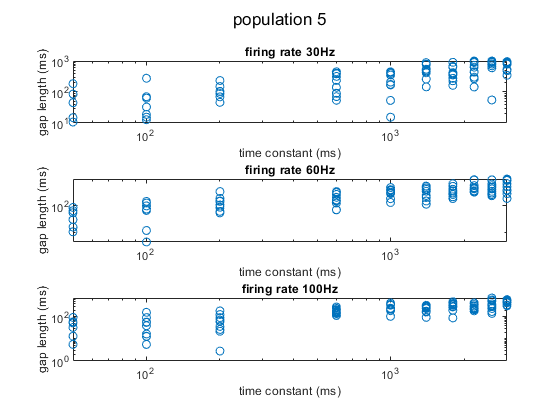

rows = find(fr2_round == 3 & corr_bin==2);
fr_rows = fr(rows);
j_vals = [1 2 11]; % firing rates 30, 60, 100 
if ~isempty(rows)
    all_X = [];
    all_Y = [];
    for j = 1:length(j_vals)
        row = rows(j_vals(j));  
        tau_vec = c{row,1}.performance(:,1);
        Gap = zeros(length(tau_vec),ntrials);
        for i = 1:ntrials
            Gap(:,i) = c{row,i}.performance(:,2);
        end
        Gap2 = reshape(Gap,1,[]);
        Tau = repmat(tau_vec,ntrials,1);       
        subplot(3,1,j)
        loglog(Tau,Gap2,'o')
        xlabel('time constant (ms)')
        ylabel('gap length (ms)')
        title(['firing rate ', num2str(fr_rows(j_vals(j))), 'Hz'])
    end
end  
sgtitle('population 5')

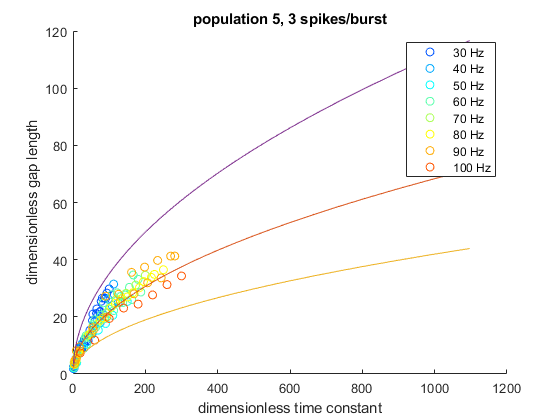

close all hidden;
mycolors = jet(10);

rows = find(fr2_round == 3 & corr_bin==2);
all_X = zeros(10,length(rows));
all_Y = zeros(10,length(rows));
all_X1 = [];
all_Y1 = [];
for j = 1:length(rows)
    row = rows(j);  
    tau_vec = c{row,1}.performance(:,1);
    Gap = zeros(length(tau_vec),ntrials);
    for i = 1:ntrials
        Gap(:,i) = c{row,i}.performance(:,2);
    end
    Gap2 = reshape(Gap,1,[]);
    Tau = repmat(tau_vec,ntrials,1);
        
    X = Tau.*fr_exact(row)./1000;
    Y = Gap2.*fr_exact(row)./1000;
    % can average Y values that have the same X value (average across
    % trials)
    X_vals = unique(X);
    Y_vals = zeros(length(X_vals),1);
    for i = 1:length(X_vals)
        Y_vals(i) = median(Y(X==X_vals(i)),'omitnan');
    end
    this_color = fr(row)/10;
    %loglog(X_vals, Y_vals, 'o', 'Color', mycolors(this_color,:))
    %hold on
    all_X(:,j) = X_vals;
    all_Y(:,j) = Y_vals;
end
    
    
% now average together all points that have the same x value if they
% have same total fr
for i = 1:length(fr_vals)
    col = find(fr(rows) == fr_vals(i));
    this_x = all_X(:,col);
    this_y = all_Y(:,col);
    this_x = reshape(this_x,[],1);
    this_y = reshape(this_y,[],1);
    x_vals = unique(this_x);
    y_vals = zeros(length(x_vals),1);
    for j = 1:length(x_vals)
        y_vals(j) = median(this_y(this_x == x_vals(j)));
    end
    loglog(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
    all_X1 = [all_X1; x_vals];
    all_Y1 = [all_Y1; y_vals];
    hold on
end
    
X = log(all_X1);
Y = log(all_Y1);
Y = Y(~isnan(Y));
X = X(~isnan(Y));
xx = log(1):0.1:7;
[p, S, mu] = polyfit(X,Y,1);
[yy, delta] = polyval(p,xx,S, mu);
hold on
loglog(exp(xx),exp(yy))
hold on
loglog(exp(xx),exp(yy-delta))
hold on
loglog(exp(xx),exp(yy+delta))
delta2 = exp(yy)-exp(yy-delta);
hold off
xlabel('dimensionless time constant')
ylabel('dimensionless gap length')
title('population 5, 3 spikes/burst')
legend('30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')

nrmse = 0.1385

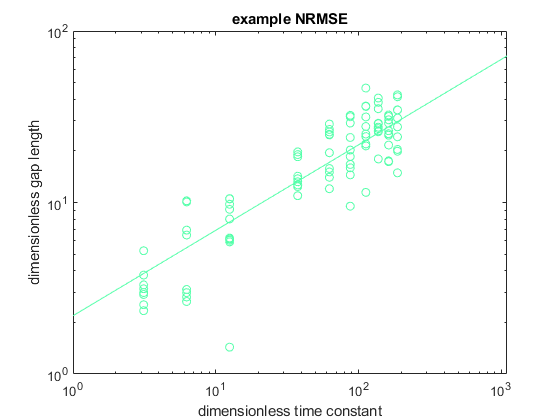

close all hidden;
for k = 1
    for l = 1
        rows = find(fr2_round == 3 & corr_bin==2);
        if ~isempty(rows)
            all_X = [];
            all_Y = [];
            for j = 51 % gives firing rate of 60 hz
                row = rows(j);  
                tau_vec = c{row,1}.performance(:,1);
                Gap = zeros(length(tau_vec),ntrials);
                for i = 1:ntrials
                    Gap(:,i) = c{row,i}.performance(:,2);
                end
                Gap2 = reshape(Gap,1,[]);
                Tau = repmat(tau_vec,ntrials,1);    
                X = Tau.*fr_exact(row)./1000;
                Y = Gap2.*fr_exact(row)./1000;
                % can average Y values that have the same X value (average across
                % trials)
                X_vals = unique(X);
                Y_vals = zeros(length(X_vals),1);
                for i = 1:length(X_vals)
                    Y_vals(i) = median(Y(X==X_vals(i)),'omitnan');
                end
                a = A(3,2);
                b = B(3,2);
                [~, goodness] = createFit1(log(X),log(Y),a,b);
                nrmse = goodness.rmse/mean(log(Y_vals),'omitnan')
                loglog(X,Y,'o','color',mycolors(6,:))
                hold on
                loglog(exp(xx),exp(yy),'color',mycolors(6,:))
                hold off
                ylabel('dimensionless gap length')
                xlabel('dimensionless time constant')
                title('example NRMSE')
            end
        end        
    end
end

## analyze data: part 2

close all hidden;
fitresult = cell(1,length(corr_vals));
for k = 1:length(corr_vals)
    rows = find(corr_bin==k);
    x = fr2(rows);
    y = NRMSE(rows);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr(rows) == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    for j = 1:length(fit_x) 
        fit_y(j) = median(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    [fitresult{k}, ~] = createFit2(fit_x, fit_y, all_x, all_y);
end

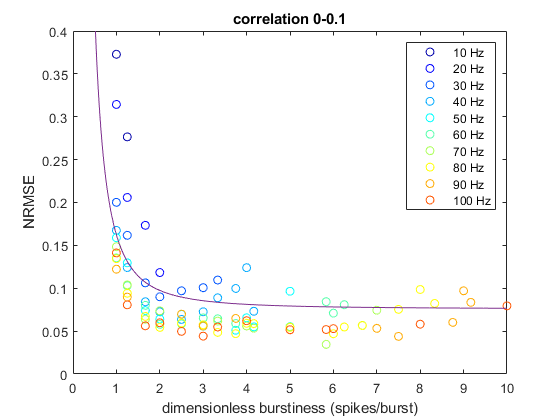

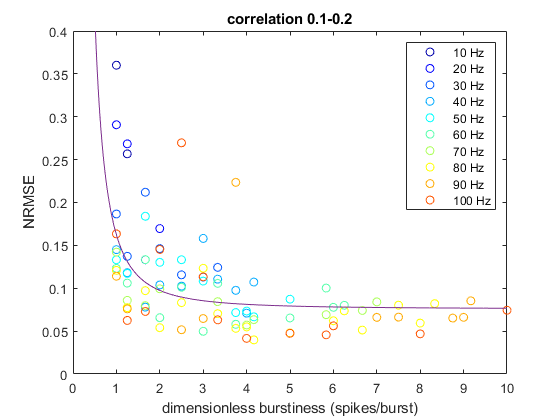

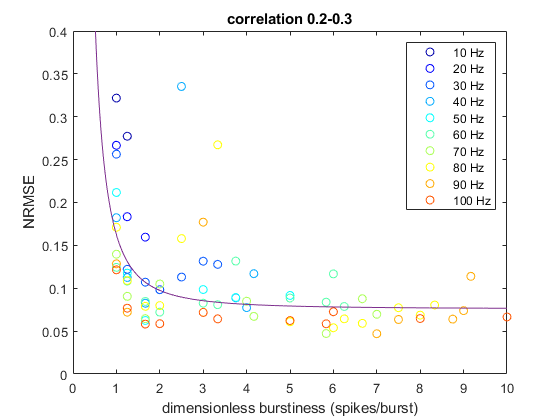

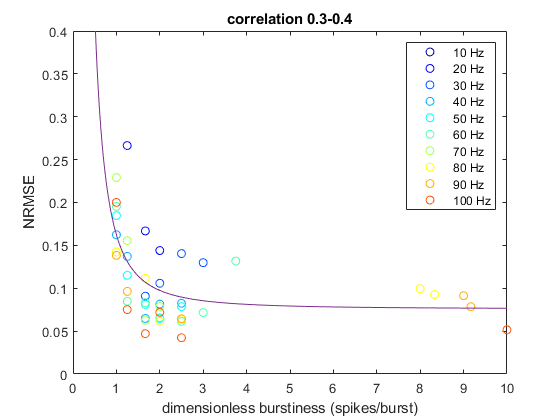

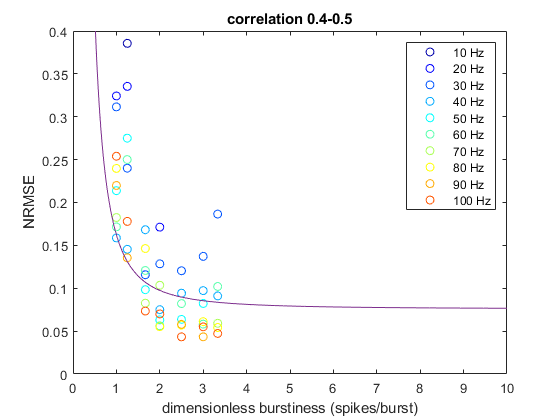

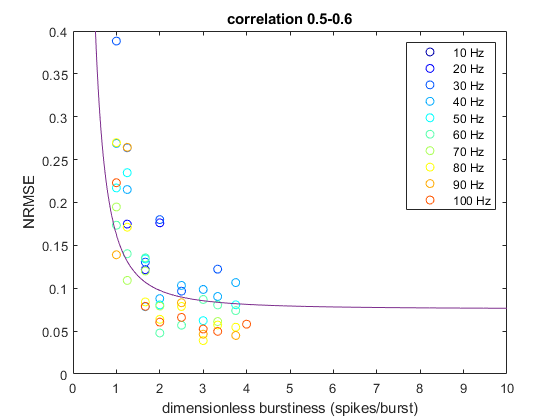

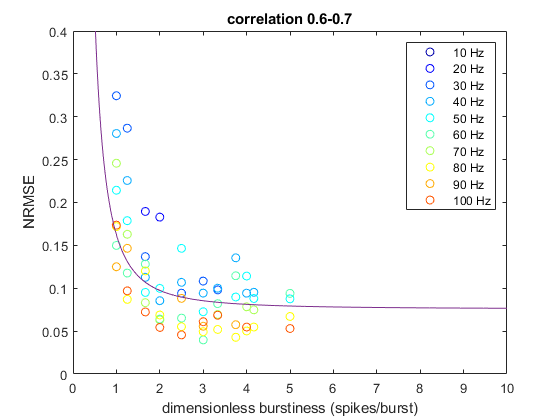

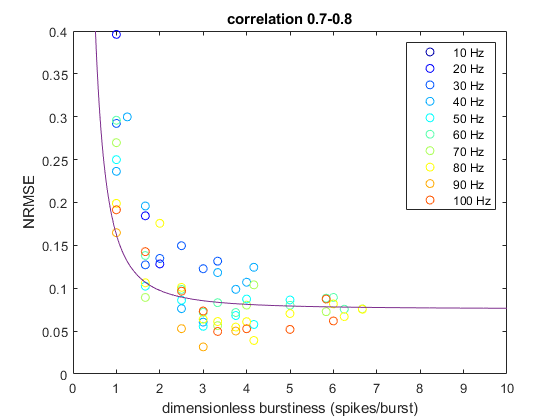

for k = 1:length(corr_vals)
    figure;
    rows = find(corr_bin==k);
    x = fr2(rows);
    y = NRMSE(rows);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr(rows) == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        plot(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
        hold on
    end
    
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    for j = 1:length(fit_x) 
        fit_y(j) = median(all_y(all_x == fit_x(j)));
    end
        
    xx = 0.5:0.01:10;    
    yy = fit(xx);
    plot(xx,yy)
    xlim([0 10])
    ylim([0 0.4])
    ylabel('NRMSE')
    xlabel('dimensionless burstiness (spikes/burst)')  
    title(['correlation ', num2str(corr_vec1(k)), '-', num2str(corr_vec1(k+1))])
    legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')
end

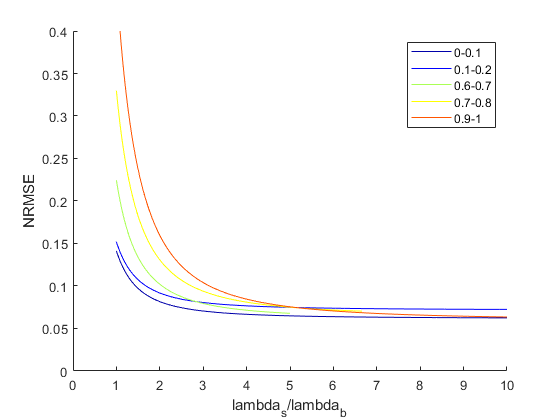

mycorrs = [1 2 7 8 10];
close all hidden;
for k = 1:length(mycorrs)
    rows = find(corr_bin==mycorrs(k));
    x = fr2(rows);
    y = NRMSE(rows);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr(rows) == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
        hold on
    end
    xx = 1:0.01:max(all_x);
    yy = fitresult{mycorrs(k)}(xx);
    plot(xx,yy,'Color',mycolors(mycorrs(k),:))
    hold on
    xlim([0 10])
    ylim([0 0.4])
    M1(1:length(xx),k*2-1:k*2) = [xx.' yy];
end
hold off
ylabel('NRMSE')
xlabel('lambda_s/lambda_b') 
legend('0-0.1','0.1-0.2','0.6-0.7','0.7-0.8','0.9-1')

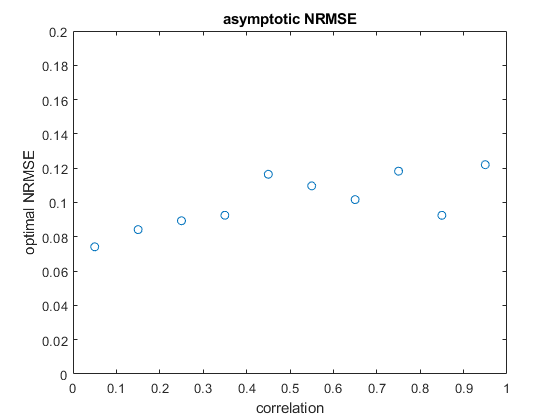

optimal_burst_prediction = zeros(length(corr_vals),1);
optimal_nrmse_prediction = zeros(length(corr_vals),1);
for k = 1:length(corr_vals)
    rows = find(corr_bin==k);
    x = fr2(rows);
    y = NRMSE(rows);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr(rows) == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
        hold on
    end
    xx = 1:0.01:max(all_x);
    yy = fitresult{k}(xx);
    plot(xx,yy,'Color',mycolors(k,:))
    hold on
    xlim([0 10])
    ylim([0 0.4])
    [res_x, ind] = knee_pt(yy,xx);
    optimal_burst_prediction(k) = res_x;
    optimal_nrmse_prediction(k) = yy(ind);
end
hold off
ylabel('NRMSE')
xlabel('dimensionless burstiness (spikes/burst)') 
legend('0-0.1','0.1-0.2','0.2-0.3','0.3-0.4','0.4-0.5','0.5-0.6','0.6-0.7','0.7-0.8','0.8-0.9','0.9-1')

close all hidden;
figure;
plot(corr_vec2, optimal_nrmse_prediction,'o')
ylim([0 0.2])
ylabel('optimal NRMSE')
xlabel('correlation')
title('asymptotic NRMSE')

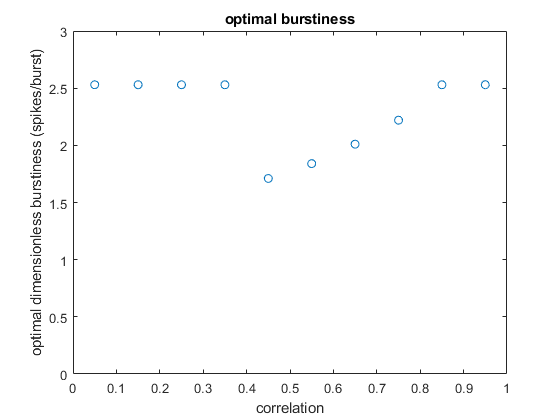


figure;
plot(corr_vec2, optimal_burst_prediction,'o')
ylim([0 3])
ylabel('optimal dimensionless burstiness (spikes/burst)')
xlabel('correlation')
title('optimal burstiness')